Control de Velocidad  de un Motor 

s= tf('s');
%% declaracion de las constantes 
k = 0.052516664;
B= 6.40115E-05;
L =5.33;
J=4.738e-9;
R= 39.3;
G_s= (k)/((s*L+R)*(s*J+B)+k*k)

G_s =
 
                 0.05252
  --------------------------------------
  2.525e-08 s^2 + 0.0003414 s + 0.005274
 
Continuous-time transfer function.





Ts=0.001;
C= pid(1,1,0)

C =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1, Ki = 1
 
Continuous-time PI controller in parallel form.



[num , den] = tfdata(C);
[num , den]= c2dm(num,den,Ts,'tustin')

num =     1.0005   -0.9995


den =      1    -1


Control_z= filt(num,den,Ts)

Control_z =
 
  1 - 0.9995 z^-1
  ---------------
     1 - z^-1
 
Sample time: 0.001 seconds
Discrete-time transfer function.




[num , den] = tfdata(G_s);
[num , den]= c2dm(num,den,Ts,'zoh');
F_z= filt(num,den,Ts)

F_z =
 
     0.1416 z^-1 + 0.01124 z^-2
  --------------------------------
  1 - 0.9847 z^-1 + 1.347e-06 z^-2
 
Sample time: 0.001 seconds
Discrete-time transfer function.



sistema_z= (Control_z*F_z)/(1+Control_z*F_z)

sistema_z =
 
                                                    
  0.1417 z^-1 - 0.4114 z^-2 + 0.3868 z^-3           
                                                    
          - 0.106 z^-4 - 0.01107 z^-5 + 1.514e-08 z^
                                                    
                                                  -6
                                                    
  ---------------------------------------------------
                                                     
  1 - 3.828 z^-1 + 5.497 z^-2 - 3.522 z^-3           
                                                     
          + 0.8636 z^-4 - 0.01107 z^-5 + 1.514e-08 z^
                                                     
                                                  -6 
                                                     
 
Sample time: 0.001 seconds
Discrete-time transfer function.



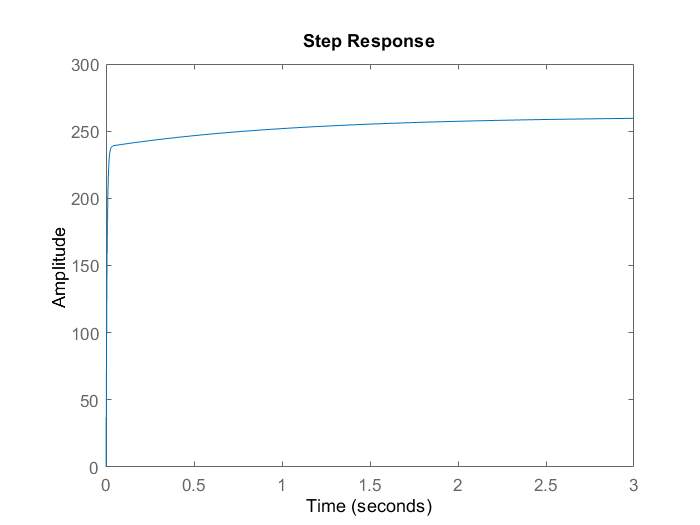


step(sistema_z*261);

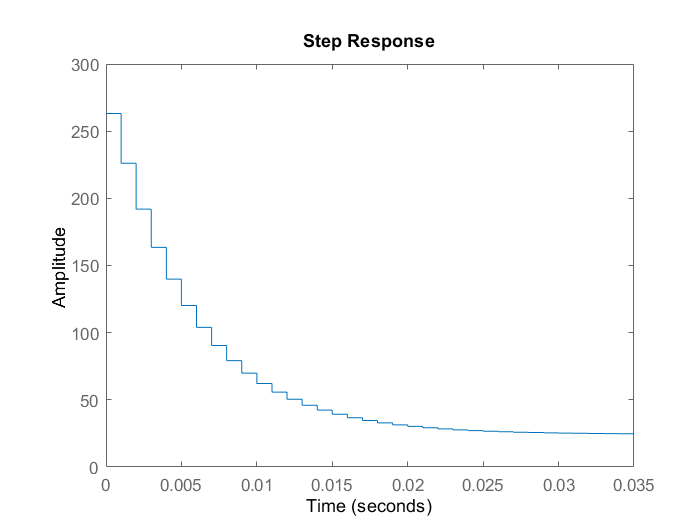

sistema2= Control_z/(1+Control_z*F_z);
step(sistema2*263);

F_z.Denominator{1}

ans =     1.0000   -0.9847    0.0000
